Goal reached!


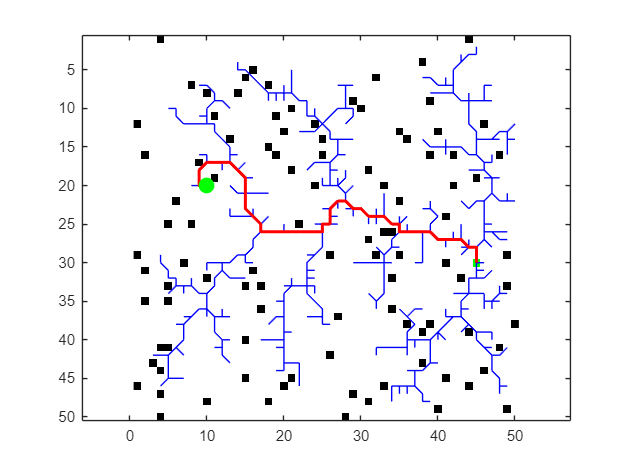

% Main Script
clear;
clc;

% Dynamic parameters
gridSize = 50;         % Size of the grid
numObstacles = 100;    % Number of obstacles
maxIterations = 5000;  % Maximum iterations for RRT
stepSize = 0.9;          % Step size for tree expansion

% Initialize grid
grid = zeros(gridSize);

% Add random obstacles
obstacles = randperm(numel(grid), numObstacles);
grid(obstacles) = 1;

% Define start and goal points
start = [30, 45]; % Starting point
goal = [20, 10];  % Goal point
grid(start(1), start(2)) = 2;
grid(goal(1), goal(2)) = 3;

% Call the RRT function
RRT(grid, start, goal, maxIterations, stepSize);


% Function Definitions
function RRT(grid, start, goal, maxIterations, stepSize)
    % Initialize tree
    tree.vertices = start; % Start point is the first vertex
    tree.edges = []; % Edges connecting vertices
    tree.parents = zeros(1, 1); % Parent tracking for path reconstruction

    % Visualization setup
    figure;
    imagesc(grid);
    colormap([1 1 1; 0 0 0; 0 1 0; 1 0 0]); % Colors for free, obstacles, start, goal
    axis equal;
    hold on;
    
    for iter = 1:maxIterations
        % Randomly sample a point in the grid
        randPoint = [randi(size(grid, 1)), randi(size(grid, 2))];

        % Find the nearest vertex in the tree
        [nearestIdx, nearestPoint] = findNearest(tree.vertices, randPoint);

        % Steer from nearestPoint towards randPoint by stepSize
        newPoint = steer(nearestPoint, randPoint, stepSize);

        % Skip if newPoint is out of bounds or collides with obstacles
        if ~isValidPoint(newPoint, grid)
            continue;
        end

        % Add newPoint to the tree
        tree.vertices = [tree.vertices; newPoint];
        tree.edges = [tree.edges; nearestPoint, newPoint];
        tree.parents(size(tree.vertices, 1)) = nearestIdx; % Track parent

        % Plot the new edge
        plot([nearestPoint(2), newPoint(2)], [nearestPoint(1), newPoint(1)], 'b');
        drawnow;

        % Check if the goal is reached
        if norm(newPoint - goal, 2) < stepSize
            disp('Goal reached!');
            plotPath(tree, start, goal, newPoint);
            return;
        end
    end

    disp('Failed to find a path.');
end

function [idx, nearest] = findNearest(vertices, point)
    distances = vecnorm(vertices - point, 2, 2);
    [~, idx] = min(distances);
    nearest = vertices(idx, :);
end

function newPoint = steer(from, to, stepSize)
    direction = to - from;
    distance = norm(direction);
    step = min(stepSize, distance);
    newPoint = round(from + step * (direction / distance));
end

function valid = isValidPoint(point, grid)
    % Check if point is within grid bounds and not an obstacle
    valid = point(1) >= 1 && point(2) >= 1 && ...
            point(1) <= size(grid, 1) && point(2) <= size(grid, 2) && ...
            grid(point(1), point(2)) ~= 1;
end

function isCollide = isCollision(p1, p2, grid)
    linePoints = bresenhamLine(p1, p2); % Use Bresenham's line algorithm
    isCollide = any(arrayfun(@(i) grid(linePoints(i, 1), linePoints(i, 2)) == 1, 1:size(linePoints, 1)));
end

function points = bresenhamLine(p1, p2)
    x1 = p1(2); y1 = p1(1);
    x2 = p2(2); y2 = p2(1);
    [x, y] = bresenham(x1, y1, x2, y2);
    points = [y', x'];
end

function plotPath(tree, start, goal, current)
    path = [current];
    while ~isequal(path(1, :), start)
        parentIdx = tree.parents(find(all(tree.vertices == path(1, :), 2)));
        parentPoint = tree.vertices(parentIdx, :);
        path = [parentPoint; path]; %#ok<AGROW>
    end
    
    % Plot the final path
    plot(path(:, 2), path(:, 1), 'r', 'LineWidth', 2);
    plot(goal(2), goal(1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
end

function [x, y] = bresenham(x1, y1, x2, y2)
    % Bresenham's line algorithm to get points on a line between (x1, y1) and (x2, y2)
    dx = abs(x2 - x1);
    dy = abs(y2 - y1);
    steep = dy > dx;
    
    if steep
        [x1, y1] = swap(x1, y1);
        [x2, y2] = swap(x2, y2);
    end
    
    if x1 > x2
        [x1, x2] = swap(x1, x2);
        [y1, y2] = swap(y1, y2);
    end
    
    dx = x2 - x1;
    dy = abs(y2 - y1);
    error = dx / 2;
    y = y1;
    ystep = -1;
    
    if y1 < y2
        ystep = 1;
    end
    
    x = x1:x2;
    yValues = zeros(size(x));
    
    for i = 1:length(x)
        yValues(i) = y;
        error = error - dy;
        if error < 0
            y = y + ystep;
            error = error + dx;
        end
    end
    
    if steep
        [x, yValues] = swap(x, yValues);
    end
    y = yValues;
end

function [a, b] = swap(a, b)
    temp = a;
    a = b;
    b = temp;
end
